addpath('Classes')
addpath('Simulink Models')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);


# Output Sliding Mode Control Research Script

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 


%Create a nonlinear decoupled EOMs object if one does not already exist. 
if (~exist('NL_Dcpld_EOMs', 'var')) 

    NL_Dcpld_EOMs = NL_Dcpld_EOMs(VDefs, BP_Kinetics); %Create an object of the class NL_Dcpld_EOMs
    NL_Dcpld_EOMs.Num_Params;
end

%Define a few symbolic variables to be used
syms y_1s y_2s y_dot_1s y_dot_2s y_ddot_1s y_ddot_2s lambda_1 lambda_2 S_1 S_2 S_dot_1 S_dot_2 


rb_global = Num_Params(subs(VDefs.R20*[VDefs.x; VDefs.y; VDefs.z_b], VDefs.symFunVec, VDefs.symVarVec), VDefs);
vb_global = Num_Params(subs(BP_Knmtcs.vb2s, VDefs.symFunVec, VDefs.symVarVec), VDefs);
ab_global = Num_Params(subs(BP_Knmtcs.ab2s, VDefs.symFunVec, VDefs.symVarVec), VDefs);

## System 1 - x direction

### Sliding Surface for global x location of the ball 

out_y1_NL = rb_global(1)

$$out\_y1\_NL = 0.0605\,\cos\left(\gamma \right)\,\sin\left(\beta \right)+x\,\cos\left(\beta \right)+y\,\sin\left(\beta \right)\,\sin\left(\gamma \right)$$

out_y1d_NL = vb_global(1)

$$out\_y1d\_NL = \dot{x}+0.0605\,\dot{\beta }\,\cos\left(\gamma \right)+\dot{\beta }\,y\,\sin\left(\gamma \right)$$

out_y1dd_NL = ab_global(1)

$$out\_y1dd\_NL = \ddot{x}+0.0605\,\ddot{\beta }\,\cos\left(\gamma \right)-{\dot{\beta }}^{2}\,x-0.1210\,\dot{\beta }\,\dot{\gamma }\,\sin\left(\gamma \right)+\ddot{\beta }\,y\,\sin\left(\gamma \right)+2\,\dot{\beta }\,\dot{y}\,\sin\left(\gamma \right)+2\,\dot{\beta }\,\dot{\gamma }\,y\,\cos\left(\gamma \right)$$

out_y1_NL_Dcpld = subs(out_y1_NL, VDefs.gamma, 0)

$$out\_y1\_NL\_Dcpld = 0.0605\,\sin\left(\beta \right)+x\,\cos\left(\beta \right)$$

out_y1d_NL_Dcpld = subs(out_y1d_NL, [VDefs.gamma VDefs.gamma_dot], [0 0])

$$out\_y1d\_NL\_Dcpld = \dot{x}+0.0605\,\dot{\beta }$$

out_y1dd_NL_Dcpld = subs(out_y1dd_NL, [VDefs.gamma VDefs.gamma_dot VDefs.gamma_ddot], [0 0 0])

$$out\_y1dd\_NL\_Dcpld = -{\dot{\beta }}^{2}\,x+\ddot{x}+0.0605\,\ddot{\beta }$$

$\begin{array}{l}

S_1 = \dot{y}_1 + \lambda_1 \, y_1\\

S_1 = \dot{x} +\dot{\beta} \,z_b  + \lambda_1 \,(\,x \, cos(\beta)+ z_b \, sin(\beta))

\end{array}

$NEED TO CHANGE


S1_eqn = S_1 == y_dot_1s - out_y1d_NL_Dcpld + lambda_1*( y_1s - out_y1_NL_Dcpld)

$$S1\_eqn = S_{1}=-\dot{x}+{\dot{y}}_{\mathrm{1s}}-0.0605\,\dot{\beta }+\left(y_{\mathrm{1s}}-0.0605\,\sin\left(\beta \right)-x\,\cos\left(\beta \right)\right)\,\lambda_{1}$$


Sd1_eqn = S_dot_1 == y_ddot_1s - out_y1dd_NL_Dcpld + lambda_1*(y_dot_1s - out_y1d_NL_Dcpld)

$$Sd1\_eqn = {\dot{S}}_{1}={\ddot{y}}_{\mathrm{1s}}-\ddot{x}-0.0605\,\ddot{\beta }+{\dot{\beta }}^{2}\,x-\lambda_{1}\,\left(\dot{x}-{\dot{y}}_{\mathrm{1s}}+0.0605\,\dot{\beta }\right)$$

Sd1_eqn = S_dot_1 == expand(subs(rhs(Sd1_eqn), [VDefs.x_ddot, VDefs.beta_ddot], [rhs(NL_Dcpld_EOMs.NumDcpldEOMs(2)), rhs(NL_Dcpld_EOMs.NumDcpldEOMs(4))]))

$$Sd1\_eqn = {\dot{S}}_{1}={\ddot{y}}_{\mathrm{1s}}-0.0605\,\dot{\beta }\,\lambda_{1}-\lambda_{1}\,\dot{x}+\lambda_{1}\,{\dot{y}}_{\mathrm{1s}}-\frac{0.1000\,T_{\beta }}{0.2100\,x^{2}+0.0182}+{\dot{\beta }}^{2}\,x-\frac{0.1448\,\sin\left(\beta \right)}{0.2100\,x^{2}+0.0182}-\frac{0.0129\,{\dot{\beta }}^{2}\,x}{0.2100\,x^{2}+0.0182}-\frac{0.0294\,x\,\cos\left(\beta \right)}{0.2100\,x^{2}+0.0182}-\frac{0.1500\,{\dot{\beta }}^{2}\,x^{3}}{0.2100\,x^{2}+0.0182}-\frac{1.4715\,x^{2}\,\sin\left(\beta \right)}{0.2100\,x^{2}+0.0182}+\frac{0.0060\,\dot{\beta }\,x\,\dot{x}}{0.2100\,x^{2}+0.0182}$$

### Lyapunov Function and Switching Law


$$\begin{array}{l}

V_1 = \frac{S_1^^2}{2}\\

\dot{V}_1 = S_1 \, \dot{S}_1

\end{array}$$


% Vd1 = rhs(S1_eqn)*rhs(Sd1_eqn)
Vd1 = S_1*rhs(Sd1_eqn)

$$Vd1 = -S_{1}\,\left(0.0605\,\dot{\beta }\,\lambda_{1}-{\ddot{y}}_{\mathrm{1s}}+\lambda_{1}\,\dot{x}-\lambda_{1}\,{\dot{y}}_{\mathrm{1s}}+\frac{0.1000\,T_{\beta }}{0.2100\,x^{2}+0.0182}-{\dot{\beta }}^{2}\,x+\frac{0.1448\,\sin\left(\beta \right)}{0.2100\,x^{2}+0.0182}+\frac{0.0129\,{\dot{\beta }}^{2}\,x}{0.2100\,x^{2}+0.0182}+\frac{0.0294\,x\,\cos\left(\beta \right)}{0.2100\,x^{2}+0.0182}+\frac{0.1500\,{\dot{\beta }}^{2}\,x^{3}}{0.2100\,x^{2}+0.0182}+\frac{1.4715\,x^{2}\,\sin\left(\beta \right)}{0.2100\,x^{2}+0.0182}-\frac{0.0060\,\dot{\beta }\,x\,\dot{x}}{0.2100\,x^{2}+0.0182}\right)$$


Tmax = 0.075;
switching_law1 = -Tmax*sign(equationsToMatrix(Vd1, VDefs.T_beta))

$$switching\_law1 = 0.0750\,\mathrm{sign}\left(S_{1}\right)$$

## System 2 - y direction

## Desired Trajectory in x and y

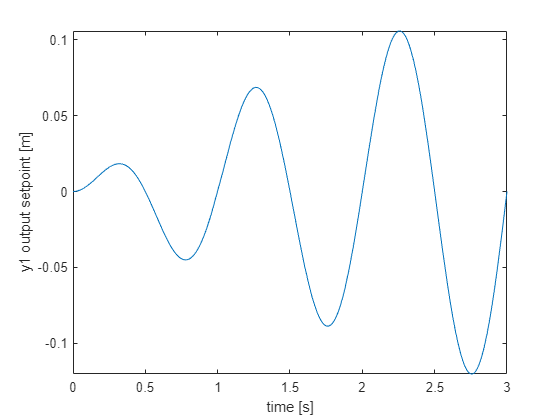


r_sim = .2; % radius of circular trajectory [m]
freq = 1; %rotations per second
omega_sim =  2*pi*freq; %angular frequency of circular trajectory 

%Trajectory symfuns figure 8
des_traj_sym_y1(VDefs.t) = r_sim*sin(omega_sim*VDefs.t);
des_traj_sym_y2(VDefs.t) = r_sim*sin(omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);


%Overlay first order smoothing function
T = 3; %Time constant for first order response

%Trajectory symfuns with first order smoothing overlayed
des_traj_sym_y1(VDefs.t) = des_traj_sym_y1(VDefs.t)*(1-exp(-VDefs.t/T));
des_traj_sym_y2(VDefs.t) = des_traj_sym_y2(VDefs.t)*(1-exp(-VDefs.t/T));

fplot(des_traj_sym_y1) 
xlim([0 2*pi/omega_sim*3]); 
ylabel('y1 output setpoint [m]')
xlabel('time [s]')

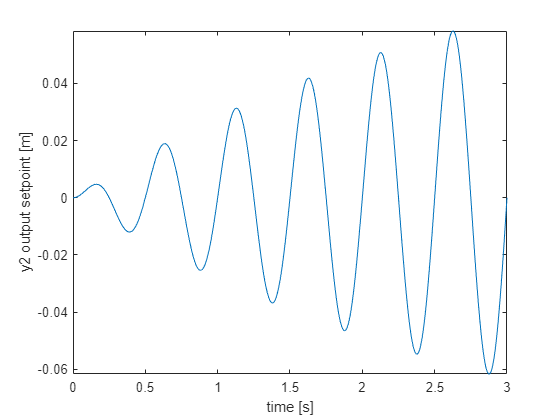


fplot(des_traj_sym_y2) 
xlim([0 2*pi/omega_sim*3]); 
ylabel('y2 output setpoint [m]')
xlabel('time [s]')


%Trajectory's derivatives
des_traj_sym_dot_y1(VDefs.t) = diff(des_traj_sym_y1(VDefs.t),VDefs.t)

$$des\_traj\_sym\_dot\_y1(t) = 0.0667\,{\mathrm{e}}^{-0.3333\,t}\,\sin\left(6.2832\,t\right)-1.2566\,\cos\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)$$

des_traj_sym_dot_y2(VDefs.t) = diff(des_traj_sym_y2(VDefs.t),VDefs.t)

$$des\_traj\_sym\_dot\_y2(t) = 1.2566\,{\sin\left(6.2832\,t\right)}^{2}\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)-1.2566\,{\cos\left(6.2832\,t\right)}^{2}\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)+0.0667\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)$$

des_traj_sym_ddot_y1(VDefs.t) = diff(des_traj_sym_y1(VDefs.t),VDefs.t,2)

$$des\_traj\_sym\_ddot\_y1(t) = 0.8378\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)-0.0222\,{\mathrm{e}}^{-0.3333\,t}\,\sin\left(6.2832\,t\right)+7.8957\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)$$

des_traj_sym_ddot_y2 (VDefs.t) = diff(des_traj_sym_y2(VDefs.t),VDefs.t,2)

$$des\_traj\_sym\_ddot\_y2(t) = 0.8378\,{\mathrm{e}}^{-0.3333\,t}\,{\cos\left(6.2832\,t\right)}^{2}-0.8378\,{\mathrm{e}}^{-0.3333\,t}\,{\sin\left(6.2832\,t\right)}^{2}-0.0222\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)+31.5827\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)$$


%x_s_vec and x_y_vec
des_traj_sym_y1 = [des_traj_sym_y1;des_traj_sym_dot_y1;des_traj_sym_ddot_y1]

$$des\_traj\_sym\_y1(t) = \left[\begin{array}{c} -0.2000\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)\\ 0.0667\,{\mathrm{e}}^{-0.3333\,t}\,\sin\left(6.2832\,t\right)-1.2566\,\cos\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)\\ 0.8378\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)-0.0222\,{\mathrm{e}}^{-0.3333\,t}\,\sin\left(6.2832\,t\right)+7.8957\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right) \end{array}\right]$$

des_traj_sym_y2 = [des_traj_sym_y2;des_traj_sym_dot_y2;des_traj_sym_ddot_y2]

$$des\_traj\_sym\_y2(t) = \left[\begin{array}{c} -0.2000\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)\\ 1.2566\,{\sin\left(6.2832\,t\right)}^{2}\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)-1.2566\,{\cos\left(6.2832\,t\right)}^{2}\,\left({\mathrm{e}}^{-0.3333\,t}-1\right)+0.0667\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)\\ 0.8378\,{\mathrm{e}}^{-0.3333\,t}\,{\cos\left(6.2832\,t\right)}^{2}-0.8378\,{\mathrm{e}}^{-0.3333\,t}\,{\sin\left(6.2832\,t\right)}^{2}-0.0222\,{\mathrm{e}}^{-0.3333\,t}\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)+31.5827\,\cos\left(6.2832\,t\right)\,\sin\left(6.2832\,t\right)\,\left({\mathrm{e}}^{-0.3333\,t}-1\right) \end{array}\right]$$

## Generate all the Necessary Matlab Function Blocks in Simulink

%Replace the definition of the various MATLAB function blocks with a
%function generated from symbolic functions in the dual sliding surface control
%derivations

%% System 1 MATLAB Function Blocks
% Compute global x location of ball
sim_path_string = strcat('Output_Sliding_Mode_Control','/Controller x dimension/out_y1_NL');
load_system('Dual_Sliding_Surface_Control_Try2');
input_chars = {'x' 'beta' 'y' 'gamma'};
matlabFunctionBlock(sim_path_string, out_y1_NL  , 'FunctionName', 'y1','Vars',input_chars, 'Outputs', {'y1'})

% %% System 2 MATLAB Function Blocks
% % Compute global y location of ball
% sim_path_string = strcat('Output_Sliding_Mode_Control','/Controller x dimension/out_y1_NL');
% load_system('Dual_Sliding_Surface_Control_Try2');
% input_chars = {'x' 'beta' 'y' 'gamma'};
% matlabFunctionBlock(sim_path_string, out_y2_NL  , 'FunctionName', 'y2','Vars',input_chars, 'Outputs', {'y2'})

%%Trajectory Setpoints 
%x direction
sim_path_string = strcat('Output_Sliding_Mode_Control','/global_x_Setpoint_Function');
load_system('Dual_Sliding_Surface_Control');
matlabFunctionBlock(sim_path_string, des_traj_sym_y1,'FunctionName', 'y1_setpoint')

%y direction
sim_path_string = strcat('Output_Sliding_Mode_Control','/global_y_Setpoint_Function');
load_system('Dual_Sliding_Surface_Control');
matlabFunctionBlock(sim_path_string, des_traj_sym_y2,'FunctionName', 'y2_setpoint')

%Replace the definition of the "Plant_Function" MATLAB function block with a
%function generated from obj.plant symbolic function
sim_path_string = strcat('Output_Sliding_Mode_Control','/Plant/Plant_Function');
load_system('Dual_Sliding_Surface_Control');
%Generate a matlab function from the linearized plant model
input_chars = {'x', 'x_dot', 'beta', 'beta_dot','y', 'y_dot', 'gamma', 'gamma_dot', 'T_beta', 'T_gamma' };
matlabFunctionBlock(sim_path_string, rhs(BP_Kinetics.NL_NumEOMs), 'FunctionName', 'xdot','Vars',input_chars)


## Simulate the Dual Sliding Surface Controller

%Specify simulation time
tspan = [0 2*pi/omega_sim]*3;
% tspan = [0 2] %For checking Zach's regulator gains
%Specify initial conditions

x_0 = 0.0001*rand(8,1); %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system

Tmax = 75 %75mNm


simout_PID = sim('Dual_Sliding_Surface_Control_Try2')


function [num_thing] = Num_Params(thing, VDefs)
    %Num_ParamsInput estimated numerical parameters of the system
        %   Detailed explanation goes here
        
    
        %Numerical Parameters in terms of symbolic variables utilized in 
        %the model 
        Num_Params = [VDefs.rB  (VDefs.rC+VDefs.rB) ...
        VDefs.mB VDefs.mP VDefs.IP VDefs.IB ...
        VDefs.g_num VDefs.rG];
    
        Sym_Params = [VDefs.r_b VDefs.z_b VDefs.m_b...
            VDefs.m_p VDefs.I_p__xx VDefs.I_b VDefs.g...
            VDefs.z_p];
        
        
        %Substitute in all numerical parameters and assumptions
        num_thing = subs(thing, Sym_Params,Num_Params);
            
end